dataset;
p_l = dataset(:,2);
p_l = p_l - p_l(1,1);
p_r = dataset(:,3);
p_r = p_r - p_r(1,1);
t = dataset(:,1);
delta_pl = diff(p_l);
delta_pr = diff(p_r);
delta_t = diff(t);
v_l = delta_pl./delta_t;
v_r = delta_pr./delta_t;
vt = (v_l + v_r)./2;
d = .25;
w = (v_r - v_l)./d;
integrand = w.*delta_t;


for i = 1:length(integrand)
    theta(i,:) = sum(integrand(1:i,:));
end


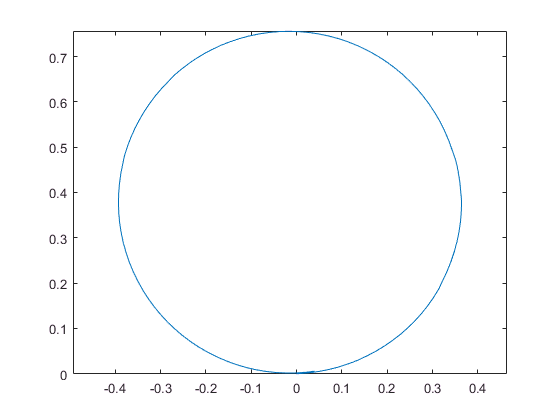

x_v= (cos(theta).*vt).*delta_t;
y_v = (sin(theta).*vt).*delta_t;


for i = 1:length(x_v)
    x_p(i,:) = sum(x_v(1:i,:));
end


for i = 1:length(y_v)
    y_p(i,:) = sum(y_v(1:i,:));
end


plot(x_p,y_p)
axis('equal')